**At first we must care about datastore **


cleandata=audioDatastore("ch2");
[cleanAudio,CleanInfo] = read(cleandata);
bonedata=audioDatastore("ch1");   


[boneAudio,boneInfo] = read(cleandata);
boneInfo

boneInfo = struct with fields:
    SampleRate: 44100
      FileName: 'C:\Users\Acer\Documents\MATLAB\speech\New folder\ch2\F001_A03_ch1_1_1.wav'



noise = audioread("WashingMachine-16-8-mono-1000secs.mp3");




**Extract Features Using Tall Arrays**

Tclean=tall(cleandata)

Tclean =

  M×1 tall cell array

    {165816×1 double}
    {175077×1 double}
    {216972×1 double}
    {201096×1 double}
    {232848×1 double}
    {347508×1 double}
    {179928×1 double}
    {216090×1 double}
        :        :
        :        :




Tbone=tall(bonedata)

Tbone =

  M×1 tall cell array

    {165816×1 double}
    {175077×1 double}
    {216972×1 double}
    {201096×1 double}
    {232848×1 double}
    {347508×1 double}
    {179928×1 double}
    {216090×1 double}
        :        :
        :        :






%%predictors= cellfun(@(x)addnoisetopdtr(x,noise),Tbone,'UniformOutput',false)


predictors= cellfun(@(x)chfunc(x),Tbone,'UniformOutput',false)

predictors =

  M×1 tall cell array

    {129×8×467 double}
    {129×8×493 double}
    {129×8×612 double}
    {129×8×567 double}
    {129×8×657 double}
    {129×8×982 double}
    {129×8×507 double}
    {129×8×609 double}
        :         :
        :         :




targets= cellfun(@(y)chcfunc(y),Tclean,'UniformOutput',false);



**Use gather to evaluate the targets and predictors**

predictors=gather(predictors);

Evaluating tall expression using the Parallel Pool 'local':
- Pass 1 of 1: Completed in 3 min 11 sec
Evaluation completed in 3 min 11 sec


targets=gather(targets);

Evaluating tall expression using the Parallel Pool 'local':
- Pass 1 of 1: Completed in 3 min 6 sec
Evaluation completed in 3 min 6 sec



predictors

predictors = 13×1 cell array
    {129×8×467 double}
    {129×8×493 double}
    {129×8×612 double}
    {129×8×567 double}
    {129×8×657 double}
    {129×8×982 double}
    {129×8×507 double}
    {129×8×609 double}
    {129×8×439 double}
    {129×8×583 double}
    {129×8×637 double}
    {129×8×635 double}
    {129×8×629 double}


targets

targets = 13×1 cell array
    {129×467 double}
    {129×493 double}
    {129×612 double}
    {129×567 double}
    {129×657 double}
    {129×982 double}
    {129×507 double}
    {129×609 double}
    {129×439 double}
    {129×583 double}
    {129×637 double}
    {129×635 double}
    {129×629 double}


**Normalization **


predictors = cat(3,predictors{:});

Brace indexing is not supported for variables of this type.



noisyMean = mean(predictors(:));

noisyStd = std(predictors(:));
predictors(:) = (predictors(:) - noisyMean)/noisyStd;

histogram(predictors(:))




targets = cat(2,targets{:});

cleanMean = mean(targets(:));
cleanStd = std(targets(:));
targets(:) = (targets(:) - cleanMean)/cleanStd;


**Reshape predictors and targets to the dimensions expected by the deep learning networks.**

predictors = reshape(predictors,size(predictors,1),size(predictors,2),1,size(predictors,3));

Error using reshape
Number of elements must not change. Use [] as one of the size inputs to automatically calculate the appropriate size for that dimension.

targets = reshape(targets,1,1,size(targets,1),size(targets,2));
size(targets)


predictors1=predictors(:,:,:,size(targets,4));
size(predictors)



**Randomly split the data into training and validation sets.**

You will use 1% of the data for validation during training. Validation is useful to detect scenarios where the network is overfitting the training data.

inds = randperm(size(predictors,4));
L = round(0.85*size(predictors,4));

trainPredictors = predictors(:,:,:,inds(1:L));



trainTargets = targets(:,:,:,inds(1:L));

Index in position 4 exceeds array bounds (must not exceed 1).


validatePredictors = predictors(:,:,:,inds(L+1:end));
validateTargets = targets(:,:,:,inds(L+1:end));
size(trainTargets)
size(trainPredictors)
size(validatePredictors)
size(validateTargets)

We've transform the audio to the frequency domain using the Short-Time Fourier transform (STFT), with a window length of 256 samples, an overlap of 75%, and a Hamming window. 

WindowLength = 256;
win          = hamming(WindowLength,'periodic');
overlap      = round(0.75 * WindowLength);
FFTLength    = WindowLength;
Fs           = 8e3;



numFeatures  = FFTLength/2 + 1;
numSegments  = 8;


**The fullyconnected neural network**

 
layers = [
    imageInputLayer([numFeatures,numSegments])
    fullyConnectedLayer(1032)
    dropoutLayer
    batchNormalizationLayer
    reluLayer
    
    fullyConnectedLayer(2048)
    dropoutLayer
    batchNormalizationLayer
    reluLayer
     fullyConnectedLayer(1024)
     dropoutLayer
    batchNormalizationLayer
    reluLayer
    fullyConnectedLayer(512)
    dropoutLayer
    batchNormalizationLayer
    reluLayer
    fullyConnectedLayer(512)
    dropoutLayer
    batchNormalizationLayer
    reluLayer
    fullyConnectedLayer(512)
    dropoutLayer
    batchNormalizationLayer
    reluLayer
    fullyConnectedLayer(256)
   
    batchNormalizationLayer
    reluLayer
    fullyConnectedLayer(numFeatures)
    regressionLayer
    ];




miniBatchSize=128;
options = trainingOptions("sgdm", ...
    "MaxEpochs",4, ...
    "InitialLearnRate",0.001, ...
    "MiniBatchSize",miniBatchSize, ...
    "Shuffle","every-epoch", ...
    "Plots","training-progress", ...
    "Verbose",false, ...
    "ValidationFrequency",floor(size(trainPredictors,4)/miniBatchSize), ...
    "LearnRateSchedule","piecewise", ...
    "LearnRateDropFactor",0.9, ...
    "LearnRateDropPeriod",1, ...
    "ValidationData",{validatePredictors,validateTargets})

options =   TrainingOptionsSGDM with properties:

                        Momentum: 0.9000
                InitialLearnRate: 1.0000e-03
               LearnRateSchedule: 'piecewise'
             LearnRateDropFactor: 0.9000
             LearnRateDropPeriod: 1
                L2Regularization: 1.0000e-04
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                       MaxEpochs: 4
                   MiniBatchSize: 128
                         Verbose: 0
                VerboseFrequency: 50
                  ValidationData: {[129×8×1×1173 double]  [1×1×129×1173 double]}
             ValidationFrequency: 51
              ValidationPatience: Inf
                         Shuffle: 'every-epoch'
                  CheckpointPath: ''
            ExecutionEnvironment: 'auto'
                      WorkerLoad: []
                       OutputFcn: []
                           

**Here the network being trained**

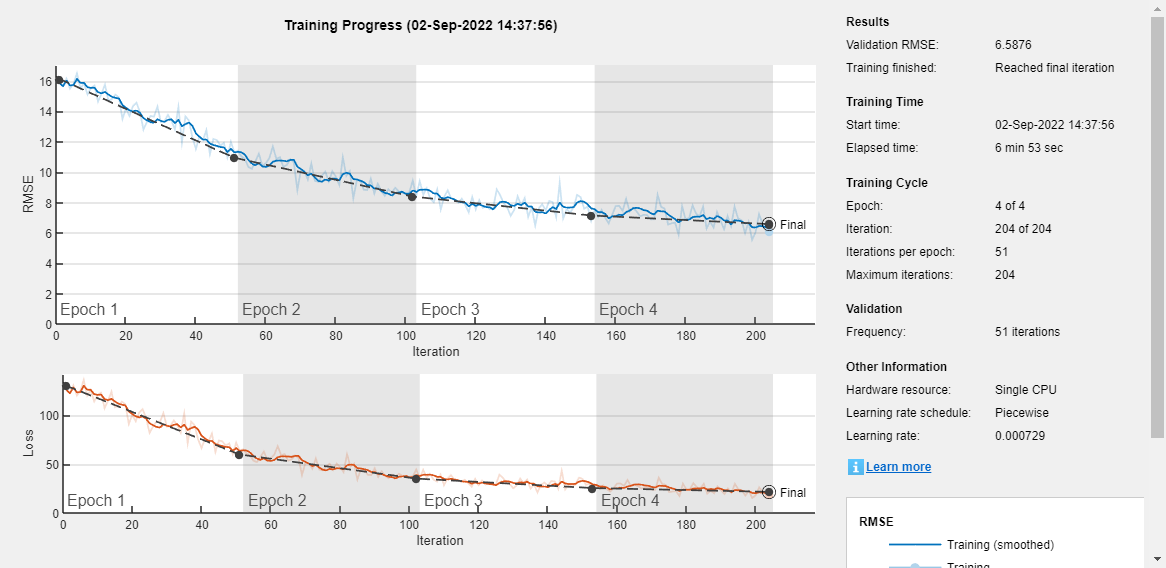

NetFullyconnected = trainNetwork(trainPredictors,trainTargets,layers,options);


save netfullyconnectedzoise.mat


**prepare a testpredictor**

**previous work that has done to predictors **

load netfullyconnected1.mat

Error using load
Cannot read file C:\Users\Acer\Documents\MATLAB\speech\New folder\netfullyconnected1.mat.



adsTest = audioDatastore("ch1");
adsTest = shuffle(adsTest);

[cleanAudio,info] = read(adsTest);
[testAudio,adsTestInfo] = read(adsTest);
inputFs      = 44100;
Fs           = 8e3;
src = dsp.SampleRateConverter("InputSampleRate", inputFs,...
                              "OutputSampleRate", Fs,...
                              "Bandwidth", 7920);
D            = 44100/8000; % Decimation factor
L            = floor( numel(testAudio)/D);
testAudio        = testAudio(1:D*L);
testAudio = testAudio(1:D*L);
testAudio=src(testAudio);
reset(src);


ind = randi(numel(noise) - numel(testAudio) + 1, 1, 1);
noiseSegment = noise(ind:ind + numel(testAudio) - 1)

noiseSegment =     0.0421
    0.0476
    0.0512
    0.0596
    0.0593
    0.0527
    0.0410
    0.0358
    0.0260
    0.0141




speechPower = sum(testAudio.^2);
noisePower = sum(noiseSegment.^2);
noiseSegment = noiseSegment .* sqrt(speechPower/noisePower)*2;
testAudio   = testAudio + noiseSegment;



testSTFT  = spectrogram(testAudio, win, overlap, FFTLength,Fs);
testPhase = angle(testSTFT);
testSTFT  = abs(testSTFT);

testSTFT = [testSTFT(:,1:numSegments-1) testSTFT];
testpredictors = zeros( numFeatures, numSegments , size(testSTFT,2) - numSegments + 1);
for index = 1:(size(testSTFT,2) - numSegments + 1)
    testpredictors(:,:,index) = testSTFT(:,index:index + numSegments - 1); 
end

testpredictors(:) = (testpredictors(:) - noisyMean) / noisyStd;

testpredictors = reshape(testpredictors, [numFeatures,numSegments,1,size(testpredictors,3)]);


**Predict clean Audio from CNN trained  network**


STFTFullyFullyconnected = predict(NetFullyconnected, testpredictors);

STFTFullyFullyconnected=STFTFullyFullyconnected';

STFTFullyFullyconnected(:) = cleanStd * STFTFullyFullyconnected(:) +  cleanMean;
%% Compute the denoised speech signals. istft performs the inverse STFT. Use the phase of the noisy STFT vectors to reconstruct the time-domain signal.
AudioFullyConnected = istft(squeeze(STFTFullyFullyconnected) .* exp(1j*testPhase), ...
    WindowLength-overlap, FFTLength, win);


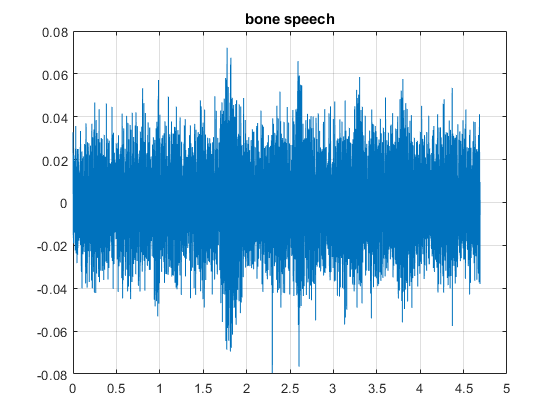


t = (1/Fs) * (0:numel(AudioFullyConnected)-1);
t1 = (1/Fs) * (0:numel(testAudio)-1);
%sound(testAudio,8000)

sound(AudioFullyConnected)
plot(t1,testAudio)
title("bone speech")
grid on

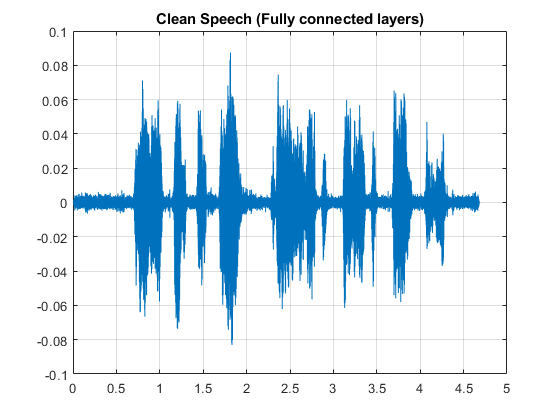

plot(t,AudioFullyConnected)
title("Clean Speech (Fully connected layers)")
grid on



%audiowrite('cttest.wav',testAudio,Fs)

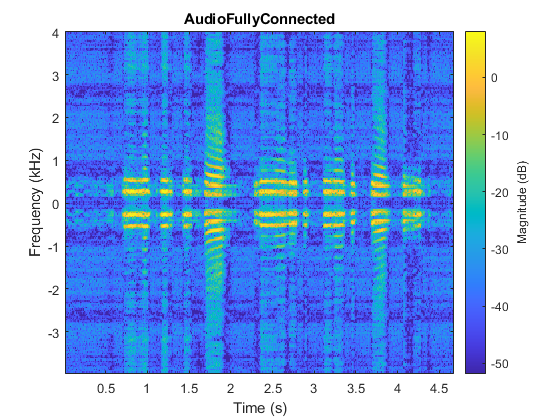


%clean_Audio=audioread('F001_A02_ch1_1_1.wav');
clean_Audio=cleanAudio;

D            = 44100/8000; % Decimation factor
L            = floor( numel(clean_Audio)/D);
audio        = clean_Audio(1:D*L);
clean_Audio = clean_Audio(1:D*L);

src = dsp.SampleRateConverter("InputSampleRate", inputFs,...
                              "OutputSampleRate", Fs,...
                              "Bandwidth", 7920);
clean_Audio=src(clean_Audio);
reset(src)
src = dsp.SampleRateConverter("InputSampleRate", inputFs,...
                              "OutputSampleRate", Fs,...
                              "Bandwidth", 7920);
bone_Audio=src(boneAudio);
sound(clean_Audio,Fs)
stft(AudioFullyConnected,Fs,'Window',win,'OverlapLength',overlap,'FFTLength',FFTLength)
title("AudioFullyConnected")

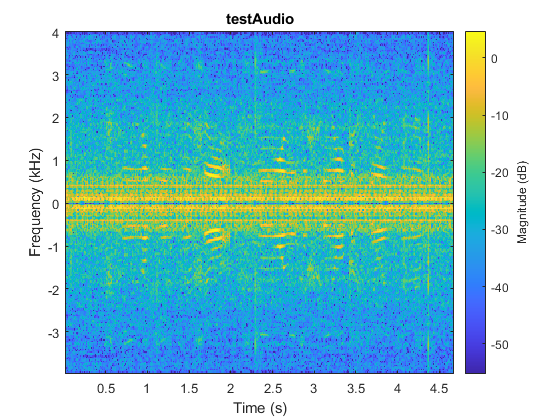

stft(testAudio,Fs,'Window',win,'OverlapLength',overlap,'FFTLength',FFTLength)
title('testAudio')

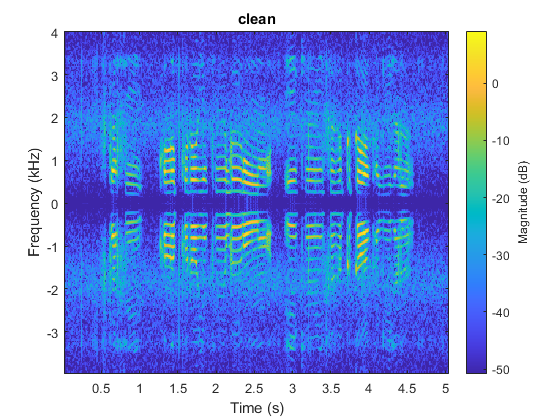


stft(clean_Audio,Fs,'Window',win,'OverlapLength',overlap,'FFTLength',FFTLength)
title('clean')



audiowrite('clean1.wav',clean_Audio,Fs)
audiowrite('enhanced1.wav',AudioFullyConnected,Fs)
audiowrite('bone1.wav',boneAudio)


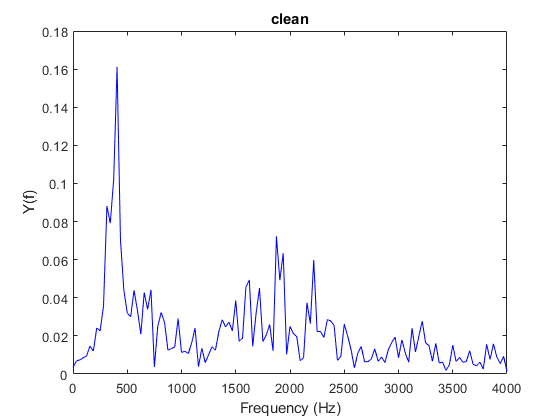

t1=1;
enhanced_seg_a=AudioFullyConnected((t1*Fs):((t1*Fs)+256-1));

clean_seg_a=clean_Audio((t1*Fs):((t1*Fs)+256-1));
bone_seg_a=bone_Audio((t1*Fs):((t1*Fs)+256-1));
[clean_seg_a_yfft f]=myfft(clean_seg_a,Fs);
[bone_seg_a_yfft f]=myfft(bone_seg_a,Fs);
[enhanced_seg_a_yfft f]=myfft(enhanced_seg_a,Fs);
MagnitudeSpectrumPlot(clean_seg_a_yfft,Fs,'b')
title('clean')

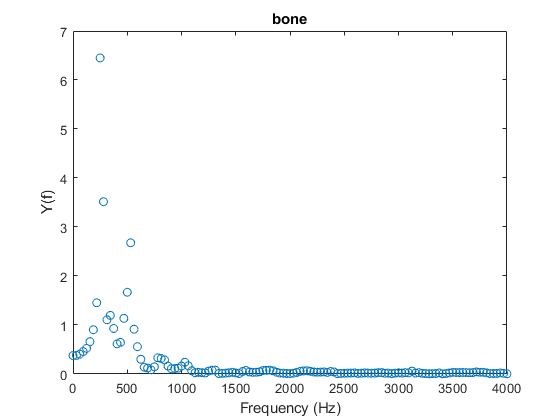

MagnitudeSpectrumPlot(bone_seg_a_yfft,Fs,'o')
title('bone')

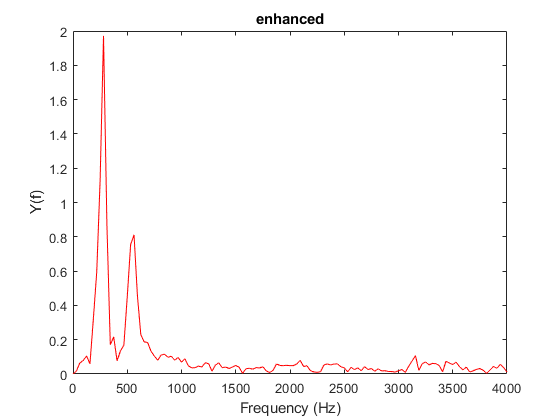


MagnitudeSpectrumPlot(enhanced_seg_a_yfft,Fs,'r')
title('enhanced')